# Compare

clear
design_params;
if true
    jaksa;
    jaksa_lv;
    jaksa_lv_oo;
    jaksa_lv_drom;
    jaksa_cam;
end

pl_A_hole = 0.7854

pl_A_hole = 0.7854

pl_A_hole = 0.7854

pl_rom = 6.2500e-04

v_stopper = 130.5724

pl_A_hole = 0.7854

jaksa_open_close = importdata("jaksa_open_close.mat");
jaksa_lv_open_close = importdata("jaksa_lv_open_close.mat");
jaksa_lv_oo_open_close = importdata("jaksa_lv_oo_open_close.mat");
jaksa_lv_drom_open_close = importdata("jaksa_lv_drom_open_close.mat");
jaksa_lv_cam_open_close = importdata("jaksa_lv_cam_open_close.mat");

## Displacement

figure('DefaultAxesFontSize',14)
semilogy(...
    jaksa_open_close.t*10^3,jaksa_open_close.x+10^-5,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.x+10^-5,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.x+10^-5,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.x+10^-5,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.x+10^-5 ...
    )
axis([0 6 10^-5 10^-2])
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [m]'), title('Plunger Displacement')

## Volume

figure('DefaultAxesFontSize',14)
plot(jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.V_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.V_ac)
legend('Choked at Main','Low Volume')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Volume [mm^3]'), title('Actuation Chamber Volume')

## Pressures

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_ac,...
     jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_ups,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
     jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('Pressures')
legend('Choked at Main AC','Choked at Main UPS','Choked at Main DPS',...
    'Low Volume AC','Low Volume UPS','Low Volume DPS')

## UPS Pressure

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.P_ups,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ups,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.P_ups,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ups,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_ups...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('UPS Pressures')

## AC Pressure

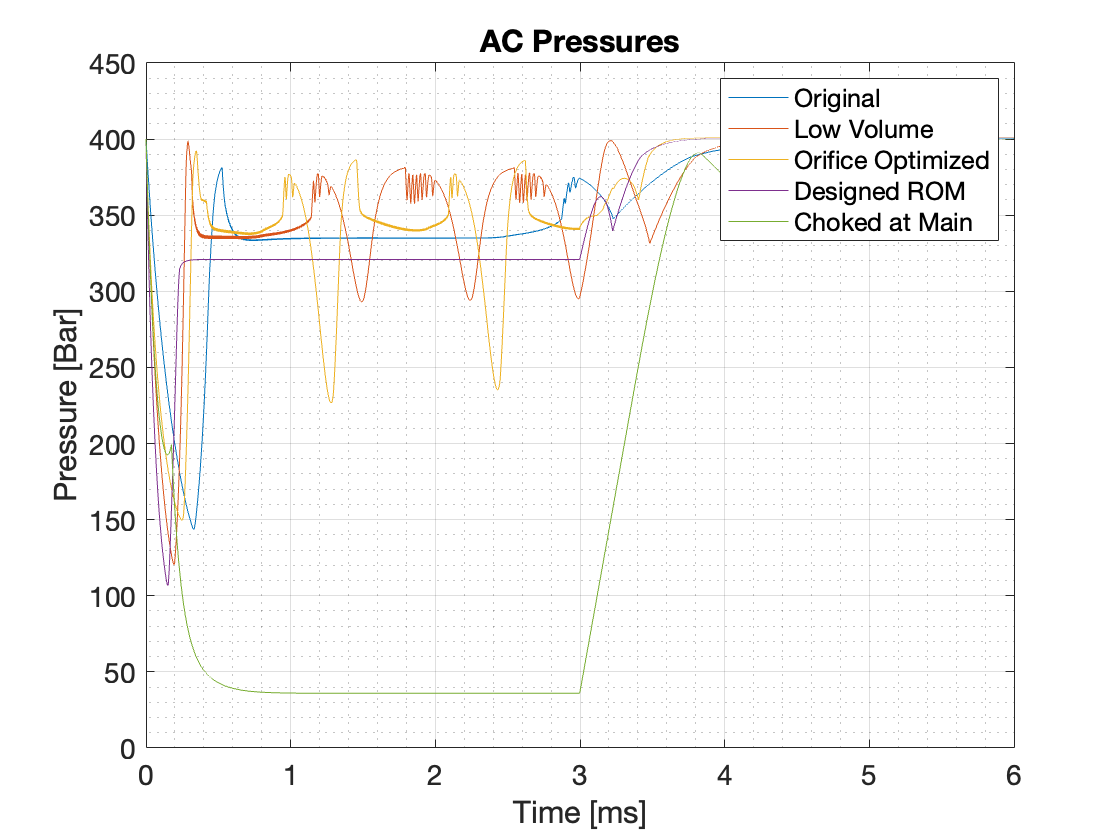

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.P_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_ac,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.P_ac,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_ac,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_ac...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('AC Pressures')

## DPS Pressure

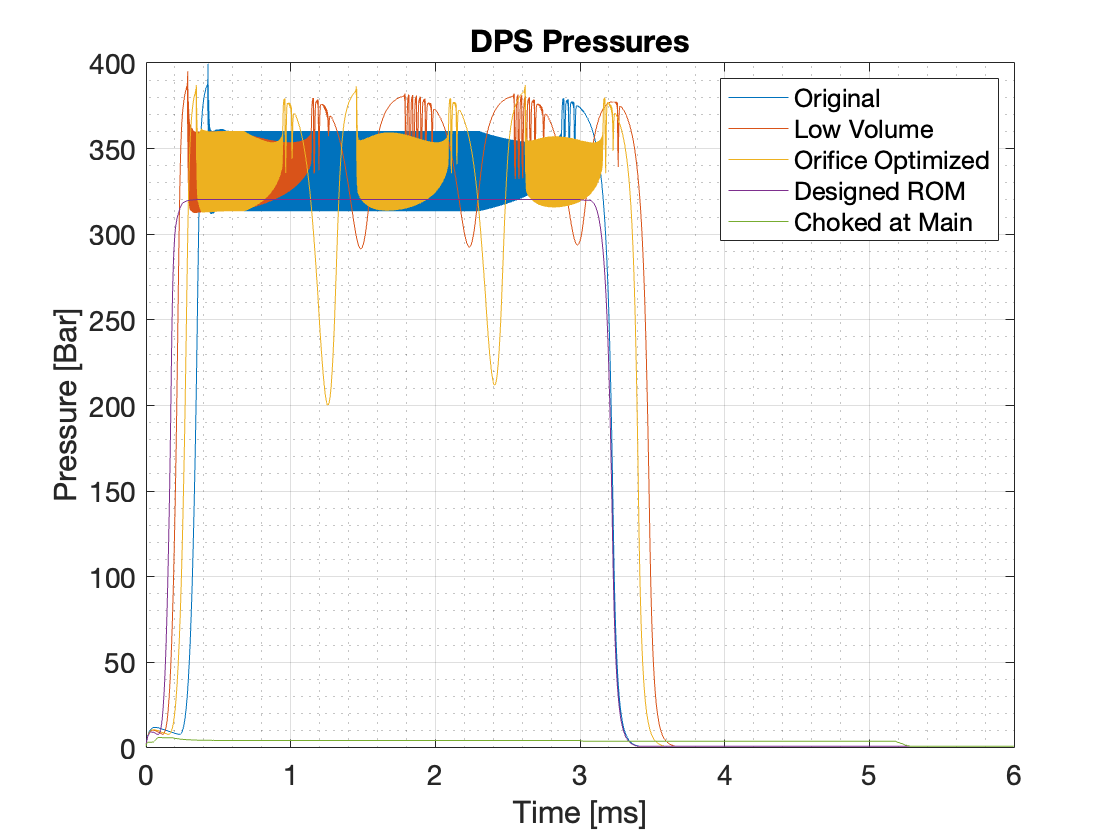

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.P_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.P_dps,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.P_dps,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.P_dps,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.P_dps...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Pressure [Bar]'), title('DPS Pressures')

## Forces

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.F_ac,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.F_u,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.F_d,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_u,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F_d,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Force [N]'), title('Forces On Plunger')
legend(...
    'Choked at Main AC','Choked at Main U','Choked at Main D','Choked at Main Net',...
    'Low Volume AC','Low Volume U','Low Volume D','Low Volume Net'...
    )

## Net force

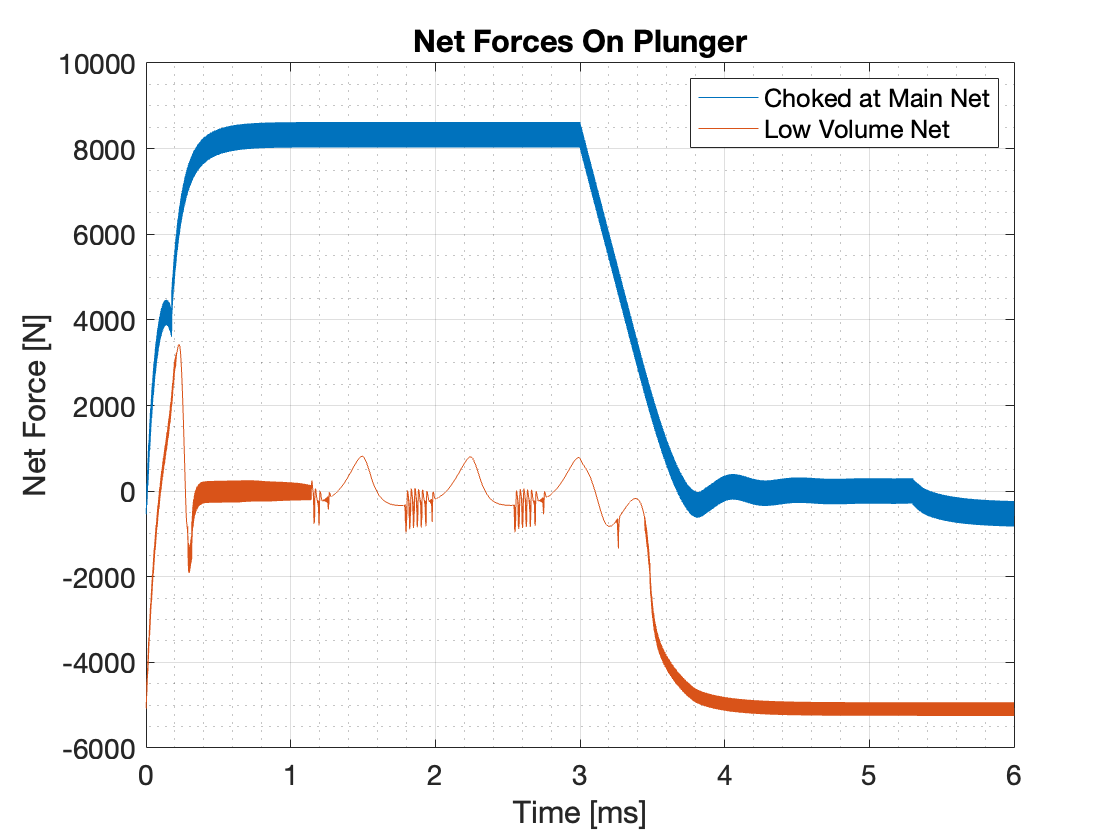

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.F,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.F...
    )
grid on, grid minor, xlabel('Time [ms]'), ylabel('Net Force [N]'), title('Net Forces On Plunger')
legend(...
    'Choked at Main Net',...
    'Low Volume Net'...
    )

## UPD to DPS

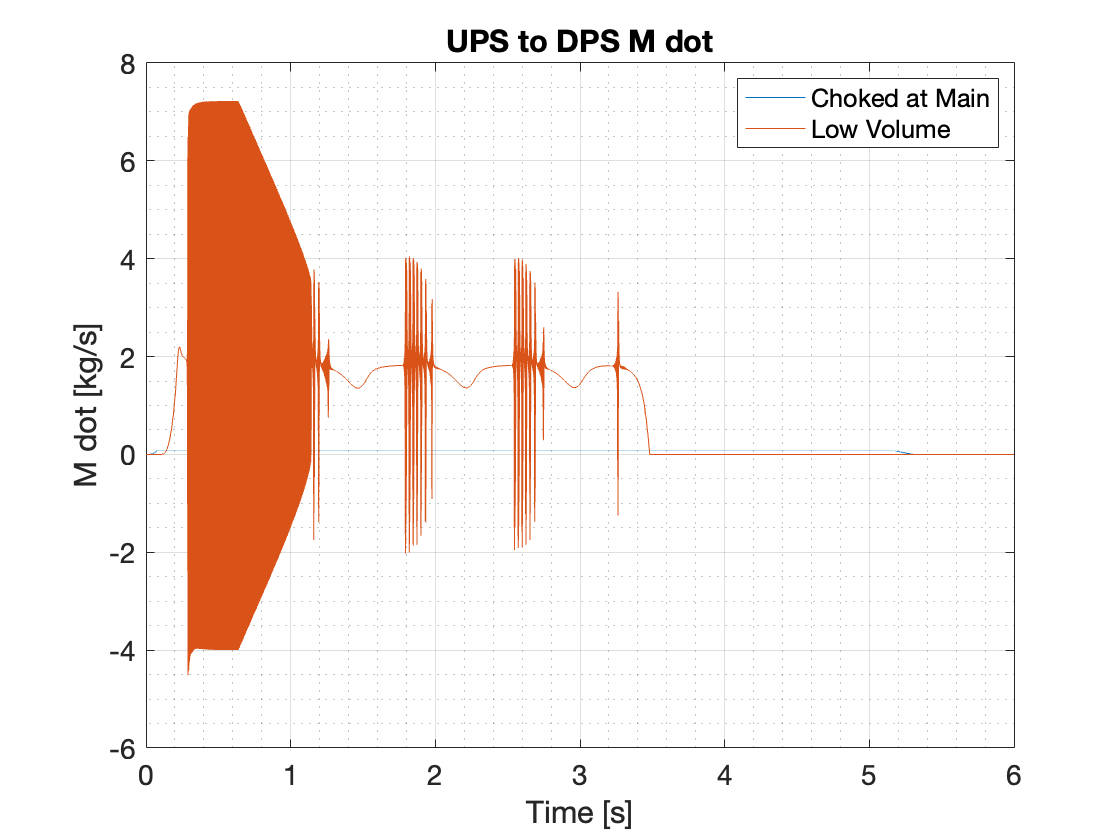

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.m_dot_ups_dps,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_dps...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to DPS M dot')
legend('Choked at Main', 'Low Volume')

## AC net m dot

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.m_dot_ups_ac,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_ups_ac...
    )
grid on, grid minor, xlabel('Time [s]'), ylabel('M dot [kg/s]'), title('UPS to AC M dot')
legend('Choked at Main', 'Low Volume')

## M dot DPS to D

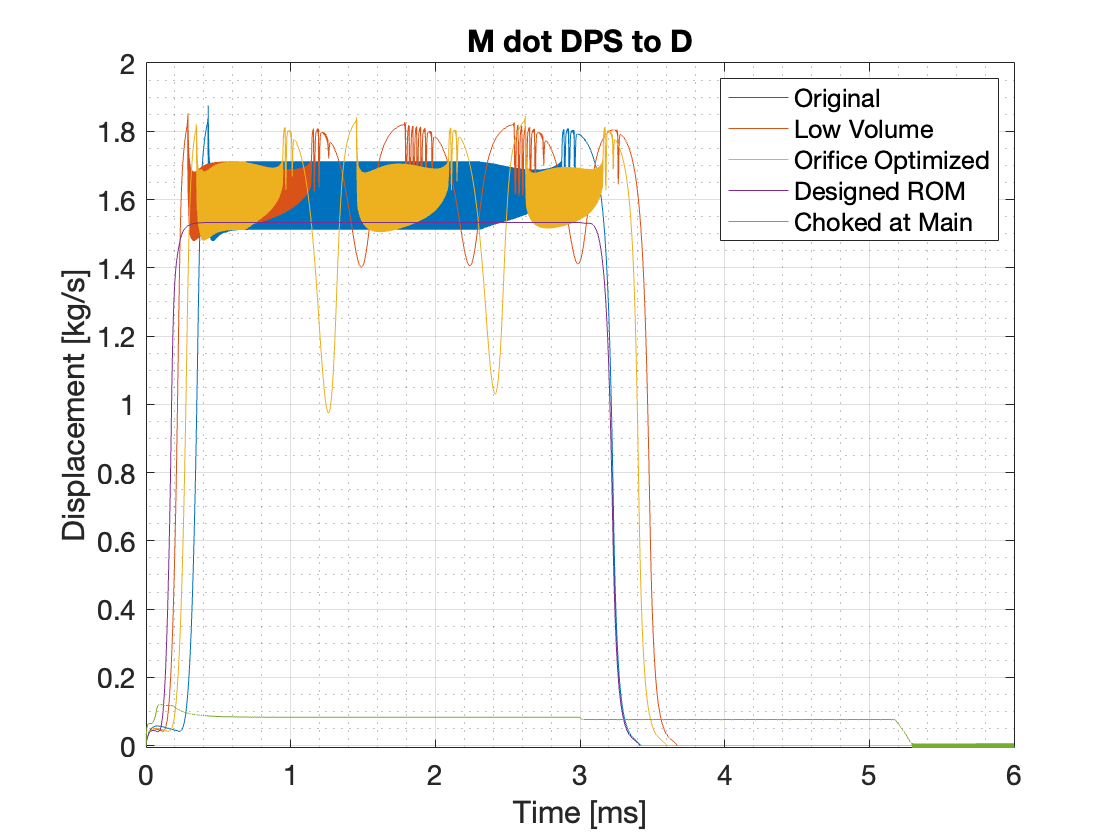

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,jaksa_open_close.m_dot_dps_d,...
    jaksa_lv_open_close.t*10^3,jaksa_lv_open_close.m_dot_dps_d,...
    jaksa_lv_oo_open_close.t*10^3,jaksa_lv_oo_open_close.m_dot_dps_d,...
    jaksa_lv_drom_open_close.t*10^3,jaksa_lv_drom_open_close.m_dot_dps_d,...
    jaksa_lv_cam_open_close.t*10^3,jaksa_lv_cam_open_close.m_dot_dps_d...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [kg/s]'), title('M dot DPS to D')

## M dot UPS to DPS

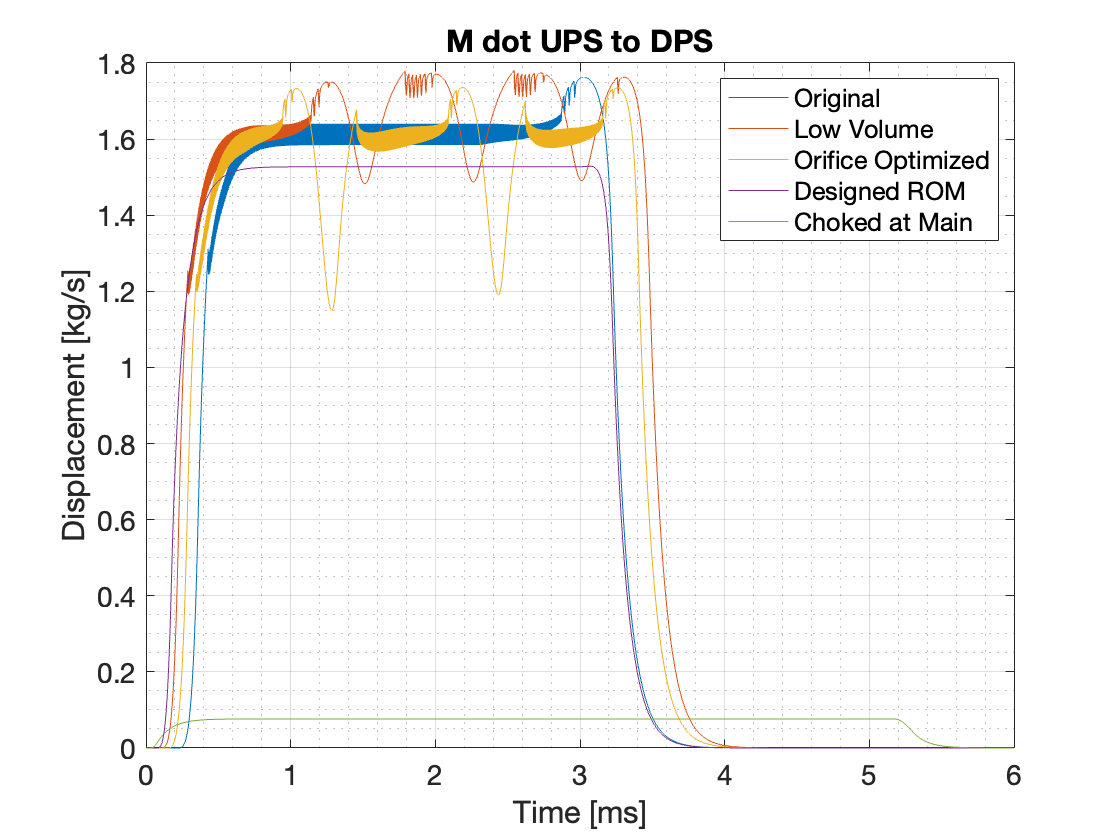

figure('DefaultAxesFontSize',14)
plot(...
    jaksa_open_close.t*10^3,simple_LPF(jaksa_open_close.m_dot_ups_dps,0.01),...
    jaksa_lv_open_close.t*10^3,simple_LPF(jaksa_lv_open_close.m_dot_ups_dps,0.01),...
    jaksa_lv_oo_open_close.t*10^3,simple_LPF(jaksa_lv_oo_open_close.m_dot_ups_dps,0.01),...
    jaksa_lv_drom_open_close.t*10^3,simple_LPF(jaksa_lv_drom_open_close.m_dot_ups_dps,0.01),...
    jaksa_lv_cam_open_close.t*10^3,simple_LPF(jaksa_lv_cam_open_close.m_dot_ups_dps,0.01)...
    )
legend('Original','Low Volume','Orifice Optimized','Designed ROM','Choked at Main')
grid on, grid minor, xlabel('Time [ms]'), ylabel('Displacement [kg/s]'), title('M dot UPS to DPS')